# **Laborator 6 - Aproximare prin metoda celor mai mici pătrate**

## **PROBLEME**

#### P1. Să se gasească aproximanta discretă prin metoda celor mai mici pătrate pentru ponderea w(x)=1 ¸si baza 1,x,x2,...,xn.

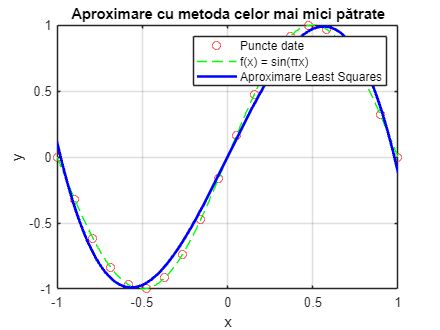

% Date de intrare
x = linspace(-1, 1, 20);       % 20 de puncte în [-1, 1]
f = sin(pi * x);              % f(x_i) = sin(pi * x_i)
n = 3;                        % Gradul polinomului

% Construirea matricei A
A = zeros(length(x), n+1);
for j = 0:n
    A(:, j+1) = x.^j;
end

% Calculul coeficienților cei mai buni (a0, a1, ..., an)
a = (A' * A) \ (A' * f');      % Solve A^T A a = A^T f

% Aproximarea pe un set de puncte fine
xx = linspace(-1, 1, 200);
P = zeros(size(xx));
for j = 0:n
    P = P + a(j+1) * xx.^j;
end

% Plot
figure;
plot(x, f, 'ro', 'DisplayName','Puncte date');
hold on;
plot(xx, sin(pi*xx), 'g--', 'DisplayName','f(x) = sin(πx)');
plot(xx, P, 'b-', 'LineWidth', 2, 'DisplayName','Aproximare Least Squares');
legend show;
title('Aproximare cu metoda celor mai mici pătrate');
xlabel('x'); ylabel('y');
grid on;

#### P2. 

**Un asteroid ce orbitează în jurul Soarelui a putut fi observat timp de câteva zile înainte să dispară. Iată 10 observații:**

**x₁:₅**

−1.024940 −0.949898 −0.866114 −0.773392 −0.671372

**x₆:₁₀**

−0.559524 −0.437067 −0.302909 −0.159493 −0.007464

**y₁:₅**

−0.389269 −0.322894 −0.265256 −0.216557 −0.177152

**y₆:₁₀**

−0.147582 −0.128618 −0.121353 −0.127348 −0.148895

Se dorește calcularea traiectoriei pe baza acestor observații pentru a putea prevedea situația când orbita va fi din nou vizibilă. Se presupune un model elipsoidal pentru orbită:

**x² = ay² + bxy + cx + dy + e.**

Acesta ne conduce la un sistem supradeterminat, care trebuie rezolvat în sensul celor mai mici pătrate pentru a determina parametrii **a, b, c, d, e**. Realizați o estimare a erorii și un test de încredere în model. Faceți același lucru pentru modelul parabolic:

**x² = ay + e.**

Care este mai probabil?

% Datele de observare
x = [-1.024940 -0.949898 -0.866114 -0.773392 -0.671372 ...
     -0.559524 -0.437067 -0.302909 -0.159493 -0.007464];

y = [-0.389269 -0.322894 -0.265256 -0.216557 -0.177152 ...
     -0.147582 -0.128618 -0.121353 -0.127348 -0.148895];

z = x.^2';

% ======================
% Modelul elipsoidal: x^2 = a*y^2 + b*x*y + c*x + d*y + e
% ======================
X_ell = [y.^2; x.*y; x; y; ones(size(x))]';
theta_ell = (X_ell' * X_ell) \ (X_ell' * z);
z_est_ell = X_ell * theta_ell;
err_ell = mean((z - z_est_ell).^2);

% ======================
% Modelul parabolic: x^2 = a*y + e
% ======================
X_par = [y; ones(size(y))]';
theta_par = (X_par' * X_par) \ (X_par' * z);
z_est_par = X_par * theta_par;
err_par = mean((z - z_est_par).^2);

% ======================
% Afișare rezultate
% ======================
fprintf("Coeficienți model elipsoidal:\n");

Coeficienți model elipsoidal:


fprintf("a = %.6f\nb = %.6f\nc = %.6f\nd = %.6f\ne = %.6f\n\n", theta_ell);

a = -1.302559
b = -0.716032
c = -0.679304
d = -3.379003
e = -0.478228




fprintf("Coeficienți model parabolic:\n");

Coeficienți model parabolic:


fprintf("a = %.6f\ne = %.6f\n\n", theta_par);

a = -3.854892
e = -0.350978




fprintf("Eroare medie pătratică:\n");

Eroare medie pătratică:


fprintf("Model elipsoidal: %.8f\n", err_ell);

Model elipsoidal: 0.00000012


fprintf("Model parabolic:  %.8f\n", err_par);

Model parabolic:  0.01178826


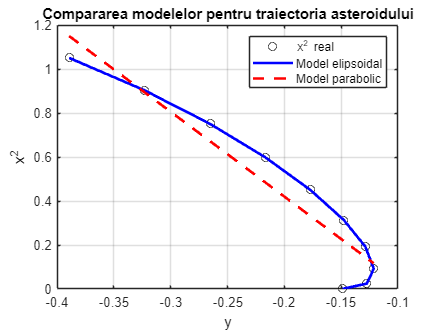


% ======================
% Plot comparativ
% ======================
figure;
plot(y, z, 'ko', 'DisplayName','x^2 real');
hold on;
plot(y, z_est_ell, 'b-', 'LineWidth', 2, 'DisplayName','Model elipsoidal');
plot(y, z_est_par, 'r--', 'LineWidth', 2, 'DisplayName','Model parabolic');
legend show;
xlabel('y'); ylabel('x^2');
title('Compararea modelelor pentru traiectoria asteroidului');
grid on;

#### P3. La măsurarea unui segment de drum, presupunem că am efectuat 5 măsurători:

**AD = 89 m**, **AC = 67 m**, **BD = 53 m**, **AB = 35 m**, și **CD = 20 m**.

Să se determine lungimile segmentelor:

**x₁ = AB**, **x₂ = BC**, și **x₃ = CD**.

% Definirea sistemului de ecuații
A = [1 1 1; 1 1 0; 0 1 1; 1 0 0; 0 0 1];
b = [89; 67; 53; 35; 20];

% Rezolvare folosind metoda celor mai mici pătrate
x = lsqlin(A, b, [], [], [], [], [0; 0; 0], [inf; inf; inf]);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Afișarea rezultatelor
fprintf('x1 (AB) = %.2f m\n', x(1));

x1 (AB) = 35.12 m


fprintf('x2 (BC) = %.2f m\n', x(2));

x2 (BC) = 32.50 m


fprintf('x3 (CD) = %.2f m\n', x(3));

x3 (CD) = 20.63 m



% Verificare
AD_calculat = x(1) + x(2) + x(3);
AC_calculat = x(1) + x(2);
BD_calculat = x(2) + x(3);
fprintf('\nVerificare:\n');


Verificare:


fprintf('AD calculat: %.2f m (masurat: 89 m)\n', AD_calculat);

AD calculat: 88.25 m (masurat: 89 m)


fprintf('AC calculat: %.2f m (masurat: 67 m)\n', AC_calculat);

AC calculat: 67.62 m (masurat: 67 m)


fprintf('BD calculat: %.2f m (masurat: 53 m)\n', BD_calculat);

BD calculat: 53.13 m (masurat: 53 m)


fprintf('AB calculat: %.2f m (masurat: 35 m)\n', x(1));

AB calculat: 35.12 m (masurat: 35 m)


fprintf('CD calculat: %.2f m (masurat: 20 m)\n', x(3));

CD calculat: 20.63 m (masurat: 20 m)


#### P4. Datele următoare dau populația SUA (în milioane) determinată la recensământul US Census, între anii 1900 și 2010. Dorim să modelăm populația și să o estimăm pentru anii 1975 și 2015.

Modelați populația printr-un model polinomial de gradul 3:

y =c0 + c1*t + c2*t^2 + c3*t^3

și printr-un model exponențial:

y =K*e^(λt).

% Datele de intrare
year = [1900, 1910, 1920, 1930, 1940, 1950, 1960, 1970, 1980, 1990, 2000, 2010, 2020]';
population = [75.995, 91.972, 105.710, 123.200, 131.670, 150.700, 179.320, 203.210, 226.510, 249.630, 281.420, 308.790, 350.686]';
t = year - 1900; % Centrare pe anul 1900

% 1. Model polinomial de gradul 3
p_poly = polyfit(t, population, 3);
y_poly = @(t) polyval(p_poly, t);

% 2. Model exponențial (liniarizat)
p_exp = polyfit(t, log(population), 1);
K = exp(p_exp(2));
lambda = p_exp(1);
y_exp = @(t) K * exp(lambda * t);

% Estimări pentru 1975 și 2015
years_predict = [1975, 2015];
t_predict = years_predict - 1900;
predictions_poly = y_poly(t_predict);
predictions_exp = y_exp(t_predict);

% Afișare rezultate
fprintf('Estimări:\n');

Estimări:


fprintf('An\tPolinomial (mil)\tExponențial (mil)\n');

An	Polinomial (mil)	Exponențial (mil)


for i = 1:length(years_predict)
    fprintf('%d\t%.2f\t\t%.2f\n', years_predict(i), predictions_poly(i), predictions_exp(i));
end

1975	211.49		207.04
2015	330.29		340.60


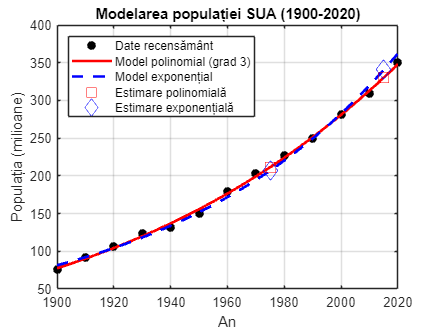


% Grafic comparativ
t_plot = linspace(0, 120, 100); % 1900-2020
figure;
plot(year, population, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Date recensământ');
hold on;
plot(t_plot + 1900, y_poly(t_plot), 'r-', 'LineWidth', 2, 'DisplayName', 'Model polinomial (grad 3)');
plot(t_plot + 1900, y_exp(t_plot), 'b--', 'LineWidth', 2, 'DisplayName', 'Model exponențial');
plot(years_predict, predictions_poly, 'rs', 'MarkerSize', 10, 'DisplayName', 'Estimare polinomială');
plot(years_predict, predictions_exp, 'bd', 'MarkerSize', 10, 'DisplayName', 'Estimare exponențială');
xlabel('An');
ylabel('Populația (milioane)');
title('Modelarea populației SUA (1900-2020)');
legend('Location', 'northwest');
grid on;